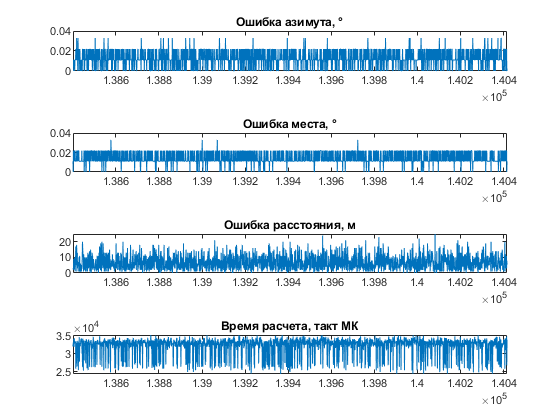

Dot indexing is not supported for variables of this type.

clear

buf_len = 1e6;

az_max = 2^15 - 1;
el_max = 2^13 - 1;
r_max = 2^23 - 1;
r_max = 2^17 - 1;

az_min = 0;
% el_min = 0;
el_min = -2^10 - 1;
r_min = 100;

in_code = [az_max - az_min, el_max - el_min, r_max - r_min] .* rand(buf_len,3) + [az_min, el_min, r_min];
in_code = round(in_code, 0);

in_sph = code2deg(in_code);
in_card = sphdeg2card(in_sph);

ind_del = in_card(:,3) > 1e6 |...
    (in_card(:,1).^2 + in_card(:,2).^2 < 100^2) |...
    in_sph(:,2) > 80;
in_card(ind_del,:) = [];
in_sph(ind_del,:) = [];
in_code(ind_del,:) = [];
clear ind_del in_card

out_ref_code = zeros(length(in_code), 3);
[out_ref_code(:,1), out_ref_code(:,2), out_ref_code(:,3)] =...
        ParalaxCalcRef(in_code(:,1), in_code(:,2), in_code(:,3));
out_ref_sph = code2deg(out_ref_code);


txData = FormTxBuf(in_code(:,1), in_code(:,2), in_code(:,3));
rxdata = uint8(zeros(length(in_code), 18)); 

s = serialport("COM1",115200, "Timeout",5, "DataBits",8,"Parity","none","StopBits",2);

tiledlayout(4,1);
pl_x = 1 : 32*64;
pl_d_az = pl_x*0;
pl_d_el = pl_x*0;
pl_d_r = pl_x*0;
pl_cnt = pl_x*0;
ax1 = nexttile;
p1 = plot(ax1,pl_x,pl_d_az);
p1.XDataSource = 'pl_x';
p1.YDataSource = 'pl_d_az';
ax2 = nexttile;
p2 = plot(ax2,pl_x,pl_d_el);
p2.XDataSource = 'pl_x';
p2.YDataSource = 'pl_d_el';
ax3 = nexttile;
p3 = plot(ax3,pl_x,pl_d_r);
p3.XDataSource = 'pl_x';
p3.YDataSource = 'pl_d_r';
ax4 = nexttile;
p4 = plot(ax4,pl_x,pl_cnt);
p4.XDataSource = 'pl_x';
p4.YDataSource = 'pl_cnt';
linkaxes([ax1, ax2, ax3, ax4], 'x');
title(ax1, 'Ошибка азимута, °');
title(ax2, 'Ошибка места, °');
title(ax3, 'Ошибка расстояния, м');
title(ax4, 'Время расчета, такт МК');

out_code = zeros(length(in_code ),3);
cycle_cnt = zeros(length(in_code ),1);
out_sph = zeros(length(in_code ),3);
delta_sph = zeros(length(in_code),3);

for i=1:buf_len    
    write(s,txData(i,:),"uint8");
    temp = read(s,18,"uint8");
    if isempty(temp)
        break;
    end
    rxdata(i,:) = temp;
    [out_code(i,1), out_code(i,2), out_code(i,3), cycle_cnt(i,1)] = UnFormRxBuf(rxdata(i,:));
    
    if mod(i, 32) == 0
        ind = i - (32 - 1) : i;
        out_sph(ind,:) = code2deg(out_code(ind,:));
        delta_sph(ind,:) = abs(out_sph(ind,:) - out_ref_sph(ind,:));
        
        if i > 32*64
            pl_x = [pl_x(32 + 1 : end),ind];
            pl_d_az = [pl_d_az(32 + 1 : end), delta_sph(ind,1)'];
            pl_d_el = [pl_d_el(32 + 1 : end), delta_sph(ind,2)'];
            pl_d_r = [pl_d_r(32 + 1 : end),   delta_sph(ind,3)'];
            pl_cnt = [pl_cnt(32 + 1 : end),   cycle_cnt(ind,1)'];
        else            
            pl_d_az(ind) = delta_sph(ind,1)';
            pl_d_el(ind) = delta_sph(ind,2)';
            pl_d_r(ind) = delta_sph(ind,3)';
            pl_cnt(ind) = cycle_cnt(ind,1)';
        end
        xlim([pl_x(1), pl_x(end) - 32]);              
        refreshdata
    end    
    pause(1/1000); 
end


result = table(...
    in_sph(:,1),in_sph(:,2),in_sph(:,3),...    
    out_sph(:,1),out_sph(:,2),out_sph(:,3),...    
    delta_sph(:,1),delta_sph(:,2), delta_sph(:,3),...
    cycle_cnt(:,1));
result.Properties.VariableNames = {...
    'in_az', 'in_el', 'in_r',...    
    'out_az', 'out_el', 'out_r',...    
    'delta_az', 'delta_el', 'delta_r',...
    'cycle_cnt'};
ind_del = (result.out_r == 0);
result(ind_del,:) = [];
clear in_sph in_card out_sph out_card delta_card delta_sph cycle_cnt

save('result_test','result');
